# **SISTEMAS DE CONTROL **

# 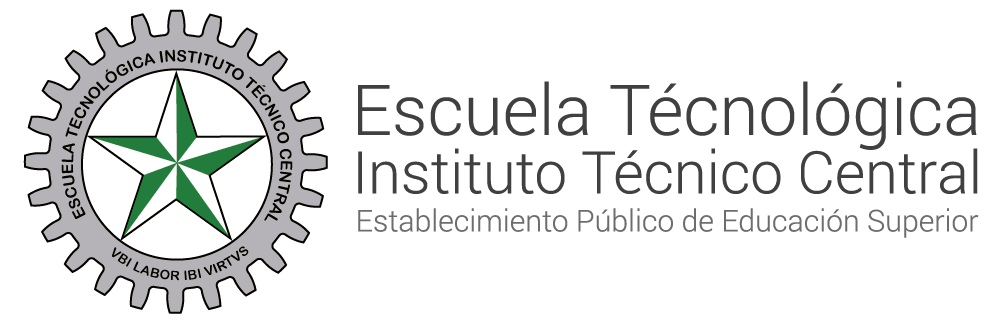

# **Sistemas de segundo órden**

#### Autor ING. JHEYSON FABIAN VILLAVISAN BUITRAGO 

#### Coautor: Eduard Fabian Espitia Fernandez

**OBJETIVO** Comprender los sistemas de primer y segundo orden en el dominio del tiempo discreto.

En el contexto de sistemas lineales e invariantes en el tiempo (LTI), que son fundamentales en la teoría de control, un sistema de segundo orden es un tipo de sistema dinámico o sistema físico que se caracteriza por tener dos polos complejos en su función de transferencia.La función de transferencia de un sistema de segundo orden en el dominio de la frecuencia (para sistemas continuos) o en el dominio Z (para sistemas discretos) tiene la forma general:

Para sistemas continuos:


$$G\left(s\right)=\frac{w_n^{\;2} }{s^2 +2\zeta w_n +w_n^{\;2} }$$


Donde 

•*K* es la ganancia del sistema.

•w_n^2 es la frecuencia natural

• 2ζw_n es el factor de amortiguamiento.

### Ejercicio de repaso

Para la siguiente función de transferencia de un sistema en lazo abierto con retroalimentación unitaria:

                           
$$G(s) = \frac {0.25}{s(s+a)}
$$
    

                     a = {0, 0.1, 0.2, ... , 1}

- Encuentre la función de transferencia en lazo cerrado.

- Encuentre la frecuencia natural.

- El factor de amortiguamiento.

- Grafique las raíces del sistema en el plano S.

- Tiempo de retardo.

- Sobreelongación Mp.

- Grafique las señales en el dominio del tiempo.

- Tiempo de asentamiento.

- Dibuje el diagrama de bloques la función de transferencia en lazo cerrado.

### **Función de transferencia en lazo abierto:**

Un sistema en lazo abierto es aquel que la señal de salida no es comparada con una señal de referencia.

Para ello se especifican las constantes del sistema en arreglos para el numerador y el denominador.

Posteriormente, se usa la función conv(),  la cual combina dos funciones o señales para producir una tercera, que describe cómo una afecta a la otra. 

clear all
clc
a=0.2      

a = 0.2000

numerador = [0.25];             
d_0 = [1 0];                    
d_1 = [1, a];                  
denominador = conv(d_0, d_1);   
fprintf('*** Función de Transferencia en lazo abierto***\n');

*** Función de Transferencia en lazo abierto***


sistema = tf(numerador, denominador)


sistema =
 
     0.25
  -----------
  s^2 + 0.2 s
 
Continuous-time transfer function.
Model Properties


### Función de transferencia en lazo cerrado:

La función de transferencia en lazo cerrado se obtiene a partir de:


$$Go = \frac {G1}{1+G1G2}$$


Sin embargo, G2 es la retroalimentación unitaria:


$$Go=\frac{G1}{1+G1}$$



$$Go = \frac{ \frac {0.25}{s(s+a)}}{1+ \frac {0.25}{s(s+a)}}$$



$$= \frac{ \frac {0.25*s(s+a)}{s(s+a)}}{s(s+a)+ \frac {0.25*s(s+a)}{s(s+a)}}$$



$$=\frac{0.25}{s^2+as+0.25}
$$


No obstante, la función *feedback *permite retornar una la función en lazo cerrado con una función en lazo abierto como parámetro de entrada y  una función de transferencia del sistema de retroalimentación. 

fprintf('*** Función de Transferencia en lazo cerrado ***\n');

*** Función de Transferencia en lazo cerrado ***


G_LazoCerrado = feedback(sistema,1)    


G_LazoCerrado =
 
         0.25
  ------------------
  s^2 + 0.2 s + 0.25
 
Continuous-time transfer function.
Model Properties


### Frecuencia natural ( $w_n$ )

Es la fecuencia con la que oscila el sistema una vez se retire la señal de excitación.

Para determinar la frecuencia natural de un sistema es importante identificar cada una de las componentes que conforman la función de transferencia de segundo órden. En términos generales está definida de la siguiente forma:

$

G(s) = K\frac{w_n^{2}}{s^{2}+2\zeta w_n s + w_n ^2}  $                           (1)     

Donde:

- K es la ganacia del sistema.

- $w_n$ es la frecuencia natural.

- $2 \zeta w_n$ es el factor de amortiguamiento.  

Por tanto, para la función de transferencia en cuestión:

K = 1          (Constante que multiplica al sistema).

$w_n^{2}$ = 0.25   (Constante que "no tiene la S" en el denominador).

$2 \zeta w_n$ = a    (Constante "que acompaña la S" en el denominador).

Al despejar la **frecuencia natural:**

$\sqrt{w_n^2}$ = $\sqrt{0.25}$

fprintf('*** Cálculo de frecuencia natural ***\n');

*** Cálculo de frecuencia natural ***


wn = sqrt(numerador)

wn = 0.5000

### Factor de amortiguamiento ( $\zeta$)

Es un parámetro adimensional que mide el grado de amortiguamiento en un sistema de segundo orden. Describe cómo se disipan las oscilaciones en un sistema dinámico debido a fricción, resistencia u otros mecanismos.

La manera de calcular $\zeta$ se determina mediante la función indicada en la ecuación 1.

Conociendo:

- $2 \zeta w_n = a$. Despejando $\zeta$ se obtiene el factor de amortiguamiento.


$$\zeta = \frac{a}{2*w_n}$$



$$\zeta = \frac{a}{2*0.5}$$



$$\zeta= a$$


fprintf('*** Cálculo de factor de amortiguamiento ***\n');

*** Cálculo de factor de amortiguamiento ***


zeta = a/(2*wn)

zeta = 0.2000

A partir del valor de $\zeta$ es posible conocer el comportamiento del sistema:

- $\zeta$ =  0 : Sistema oscilatorio.

- 0 < $\zeta$ < 1 : Sistema subamortiguado.

- $\zeta$ = 1: Sistema críticamente amortiguado.

- $\zeta$ >1 : Sistema sobre amortiguado.

fprintf('*** El comportamiento del sistema es: ***\n');

*** El comportamiento del sistema es: ***


if zeta > 0 && zeta < 1
    'El sistema es subamortiguado.'
elseif zeta==0
    'El sistema es oscilatorio.'
elseif zeta==1
    'El sistema es críticamente amortiguado.'
end

ans = 'El sistema es subamortiguado.'

### Polos

Los polos son valores característicos que indican el comportamiento en términos de estabilidad o respuesta temporal del sistema. Se caracterizan por tener una componente real y una componente imaginaria.

La manera de calcularlos es igualar la ecuación característica a cero, es decir, los valores de **s** que hacen que el denominador de la función de transferencia sea igual a cero.

$G(s)=\frac{N(s)}{D(s)}$        Los polos son los valores donde D(s)=0

#### Interpretación

- Estabilidad: En sistemas continuos, los polos en el plano **s** deben estar en el semiplano izquierdo (Re (s) < 0 ) para que el sistema sea estable.

#### Cálculo de polos

Tomando de referencia la función de transferencia en lazo cerrado:

clc
fprintf('*** Función de Transferencia en lazo cerrado ***\n');

*** Función de Transferencia en lazo cerrado ***


G_LazoCerrado = feedback(sistema,1)


G_LazoCerrado =
 
         0.25
  ------------------
  s^2 + 0.2 s + 0.25
 
Continuous-time transfer function.
Model Properties


Donde, D(s) es igual al denominador del sistema:

den = (G_LazoCerrado.Denominator);       
disp('Coeficientes del denominador:');

Coeficientes del denominador:


disp(den);

    {[1 0.2000 0.2500]}



Al igualar la función anterior a 0, se evidencia una función cuadrática donde al resolver se encuentran dos valores de **s, **los cuales indican los valores de cada polo.


$$D(s) =  S^2 + aS + 0.25 = 0$$



$$S_{1,2} = \frac{-a+-\sqrt{a^2-4*0.25}}{2} $$



$$S_{1,2} = -\frac{a}{2}+-\frac{\sqrt{a^2-1}}{2}$$


polos = pole(G_LazoCerrado)

polos =   -0.1000 + 0.4899i
  -0.1000 - 0.4899i


La manera de representarlos es mediante una "x" y para ubicarlos en el plano complejo se ubica en el "eje x" la parte real de cada polo y en el "eje y" la parte imaginaria del mismo.

Para graficar los polos basta con la función *pzmap*, sin embargo, para resaltar los polos es necesario usar la función *scatter*, la cual permite modificar parámetros en la gráfica tales como tamaño y color.  Para usar dicha función es necesario conocer la ubicación de los polos los cuales son retornados de la función *pzmap*.

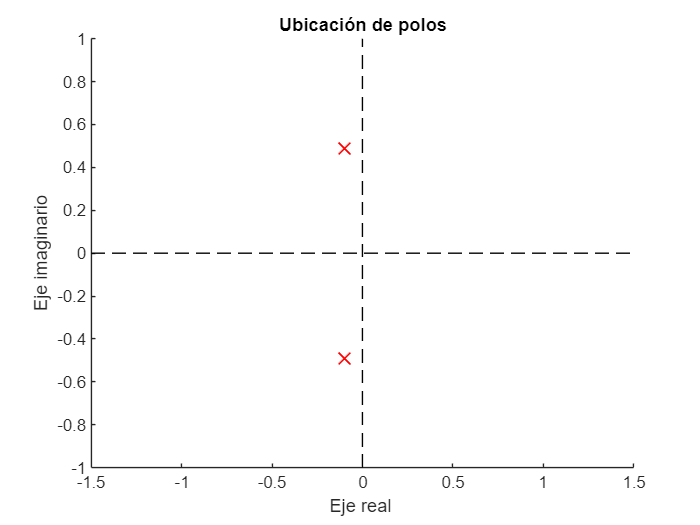

[p, z] = pzmap(G_LazoCerrado);                
figure;
hold on;
scatter(real(p), imag(p), 100, 'r', 'x', 'LineWidth', 1);
plot([-1.5 1.5], [0 0], 'k--');
plot([0 0], [-1 1], 'k--'); 
title('Ubicación de polos'); 
xlabel('Eje real ');
ylabel('Eje imaginario');

### Tiempo de retardo

El **tiempo de retardo** (o **delay time**) se refiere al tiempo que transcurre entre el momento en que un sistema recibe una entrada (estímulo) y el momento en que su salida comienza a responder.

El tiempo de retardo puede darse debido a:

#### Retardo de transporte o puro ( $T_d$): 

Se refiere a un retraso fijo en el tiempo, en el que una entrada afecta la salida después de un periodo fijo, sin transformación intermedia.

#### **Retardo asociado a la inercia del sistema**: 

Algunos sistemas necesitan tiempo para acumular energía o adaptarse antes de responder.

La manera de calcular el tiempo de retardo para un sistema subamortiguado se determina por la siguiente ecuación:


$$t_r = \frac{1}{w_d}*\arctan\left({\frac{w_d}{\zeta w_n}}\right)
$$


Donde:


$$w_d=w_n\sqrt{1 -\zeta^2}
$$


Si el sistema es críticamente amortiguado, el tiempo de retardo $t_r$ se puede aproximar utilizando la siguiente fórmula:


$$t_r \approx \frac{4}{w_n}$$


fprintf('*** Cálculo del tiempo de retardo ***\n');

*** Cálculo del tiempo de retardo ***



if zeta~=0
    wd = wn*sqrt(1-zeta^2)
    if wd>0 && wd<1
        tr = (1/wd)*atan((wd)/(zeta*wn))    
     elseif wd==0
        tr=4/wn
    end
else
    'El sistema no tiene amortiguamiento'    
    'No hay un tiempo claro para considerar que la respuesta "comienza a acercarse" al valor final.'
    tr=0;
end

wd = 0.4899

tr = 2.7954

### Sobreelongación $M_p$:

La **sobreelongación** (o sobreshoot, en inglés)  es una medida de cuánto excede la respuesta del sistema su valor final deseado durante la transición hacia el estado de equilibrio. Es posible calcular la magnitud de la sobreelongación mediante la siguiente ecuación:


$$M_p=e^{-\pi*\frac{\zeta}{\sqrt{1-\zeta^2}}}$$


fprintf('*** Cálculo de sobreelongación ***\n');

*** Cálculo de sobreelongación ***


deno = sqrt(1-zeta^2);   
r = (pi)*(zeta)/(deno);  
Mp = exp(-r)

Mp = 0.5266

### Tiempo de asentamiento $t _{Mp}$ :

Es el tiempo que tarda la respuesta de un sistema en permanecer dentro de un rango específico (típicamente el 2% o 5%) del valor final o de estado estacionario.

- Permite la presencia de oscilaciones, siempre que estas estén dentro del rango tolerado.

- Se emplea para evaluar la rapidez con la que el sistema responde y alcanza una condición aceptable de cercanía al valor deseado.

Se diferencia del tiempo de estabilización debido a que el** tiempo de asentamiento** considera márgenes definidos y puede incluir oscilaciones pequeñas aceptables y el** tiempo de estabilización** requiere que el sistema alcance un estado de equilibrio absoluto, sin oscilaciones ni cambios residuales perceptibles.

El tiempo de asentamiento se calcula mediante la ecuación:


$$t_{Mp}=\frac{n*\pi}{w_n \sqrt{1-\zeta^2}}$$


Donden $n$ es el número del pico al cual se le va a calcular el tiempo.

Para sistemas que no son subamortiguados ( $\zeta$ = 0, $\zeta$>1)  no hay tiempo de asentamiento debido a que no hay sobreelongaciones.

fprintf('*** Cálculo de tiempo de asentamiento para los tres primeros picos***\n');

*** Cálculo de tiempo de asentamiento para los tres primeros picos***


denom = wn*sqrt(1-zeta^2);   
n = 3; 
tMp = zeros(1, n);
if a>0 && a<1
for i = 1:n
    tMp(i) = i*((pi)/denom);
end
if a>0 && a<0.5

 for i = 1:n
       
   disp(['El tiempo de asentamiento para el pico ',num2str(i), ': ', num2str(tMp(i)), ' Segundos.']);
  
 end
elseif a>0.5 && a<1
    disp(['El tiempo de asentamiento para el primer pico es: ', num2str(tMp(1)), ' Segundos.']);
end

else
    'El sistema no tiene picos.'
end

El tiempo de asentamiento para el pico 1: 6.4127 Segundos.
El tiempo de asentamiento para el pico 2: 12.8255 Segundos.
El tiempo de asentamiento para el pico 3: 19.2382 Segundos.


Por su parte, el tiempo de estabilización ( $t_s$ ) con un márgen del 2% está definido por la siguiente ecuación:


$$t_{s-2\%}=\frac{4}{wn*\zeta}$$


fprintf('*** Cálculo de tiempo de estabilización: ***\n');

*** Cálculo de tiempo de estabilización: ***


ts=4/(wn*zeta)

ts = 40

Lo anterior se logra evidenciar a partir de la gráfica representativa del sistema:

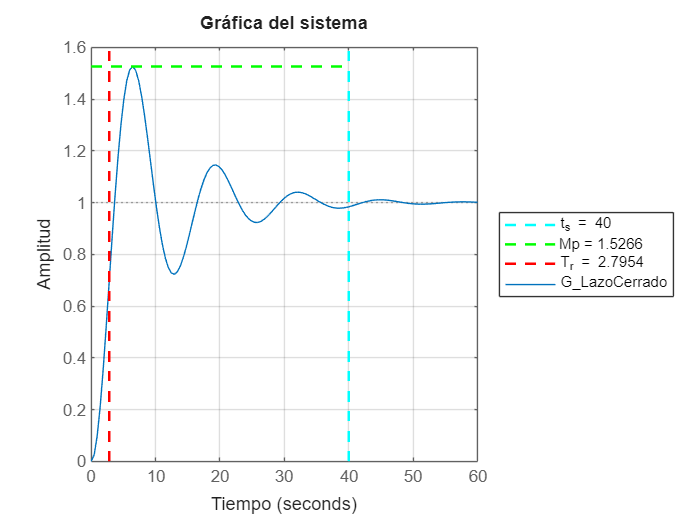

figure;           
hold on;          
plot([tr tr], [0 2], 'r--', 'LineWidth', 1.5, 'DisplayName', ['T_r = ', num2str(tr)]);
plot([0 ts], [(Mp+1) (Mp+1)], 'g--', 'LineWidth', 1.5, 'DisplayName', ['Mp = ', num2str(Mp+1)]);
plot([ts ts], [0 2], 'c--', 'LineWidth', 1.5, 'DisplayName', ['t_s = ', num2str(ts)]);
step(G_LazoCerrado);         
title('Gráfica del sistema'); 
xlabel('Tiempo');
ylabel('Amplitud');
grid on;
legend('Location','eastoutside')

if Mp==0
    'La señal no tiene sobreelongación debido a su comportamiento críticamente amortiguado. '
end

### Diagrama de bloques

Un **diagrama de bloques** es una representación gráfica de las relaciones funcionales entre los componentes de un sistema. Cada bloque en el diagrama representa una operación matemática, un subsistema o un componente físico, mientras que las líneas que conectan los bloques muestran el flujo de señales variables a través del sistema.